%{
Name: Inspection Threshold Detection 
Author: Evan Scheuritzel
Version: 1.0
Purpose: Find where quality exceeds Inspection Threshold and pass them
Input: none
Output: Out puts graph containing x Values that were inspected.
%}

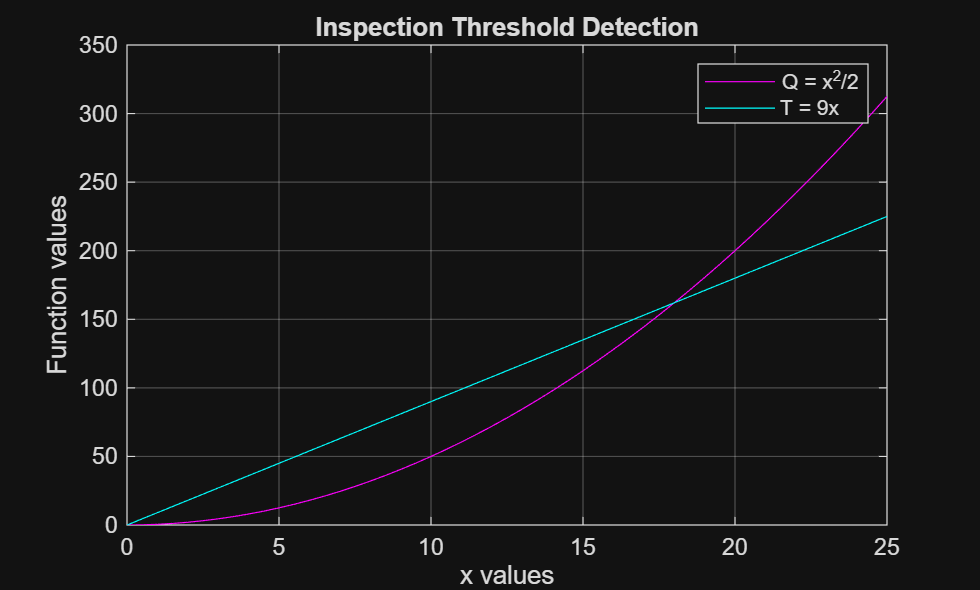

clear
x= 0:0.5:25;
Q = (x.^2)/2;
T = x*9;

plot(x,Q,'magenta');
hold on;
plot(x,T,'cyan');
legend('Q = x^2/2', 'T = 9x');
xlabel('x values');
ylabel('Function values');
title('Inspection Threshold Detection');
grid on;

% Determine where Q > T and assign 'pass' or 'fail' accordingly
isPass = Q > T;                    % logical array where Q greater than T
result = repmat("fail", size(Q));  % initialize string array of "fail"
result(isPass) = "pass";           % set "pass" where condition is true

% (Optional) display results alongside x values
disp(table(x.', Q.', T.', result.', 'VariableNames', {'x','Q','T','Result'}));

     x        Q         T      Result
    ____    ______    _____    ______

       0         0        0    "fail"
     0.5     0.125      4.5    "fail"
       1       0.5        9    "fail"
     1.5     1.125     13.5    "fail"
       2         2       18    "fail"
     2.5     3.125     22.5    "fail"
       3       4.5       27    "fail"
     3.5     6.125     31.5    "fail"
       4         8       36    "fail"
     4.5    10.125     40.5    "fail"
       5      12.5       45    "fail"
     5.5    15.125     49.5    "fail"
       6        18       54    "fail"
     6.5    21.125     58.5    "fail"
       7      24.5       63    "fail"
     7.5    28.125     67.5    "fail"
       8        32       72    "fail"
     8.5    36.125     76.5    "fail"
       9      40.5       81    "fail"
     9.5    45.125     85.5    "fail"
      10        50       90